# **Analysis 1 F001: Live cell analysis**

**Testing for:**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';

load([dataDir filesep 'C234_data.mat'],'S','settings','allIF');
% S = loadData(conditions, dataDir);
conditions = settings.conditions

conditions = 12×6 cell array
    {'GM Cdt1'      }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Aphi Cdt1'}    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Thy Cdt1' }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'GM GMNN'      }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Aphi GMNN'}    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Thy GMNN' }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'GM CCNA'      }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Aphi CCNA'}    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'Thy/Thy CCNA' }    {1×2 double}    {1×2 double}    {1×6 double}    {1×3 double}    {0×0 double}
    {'GM PCNA'      }    {1×2 double}    {1×2 double}



framesPerHr = 60/12;
frameDrugAdded = 27;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Check  stain**

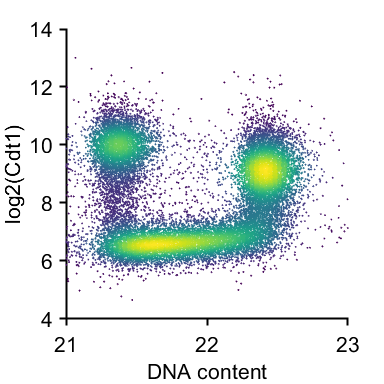

conds=[1];

xval = 'DNA';
yval = 'FarRed1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = real(log2(allIF(condition).(xval)));
    ydata =  real(log2(allIF(condition).(yval)));
%     inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
%     xdata = xdata(inds);
%     ydata = ydata(inds);
%     
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([21 23]);
%     ylim([0 10]);
    ylabel('log2(Cdt1)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis

end

**Check  stain**

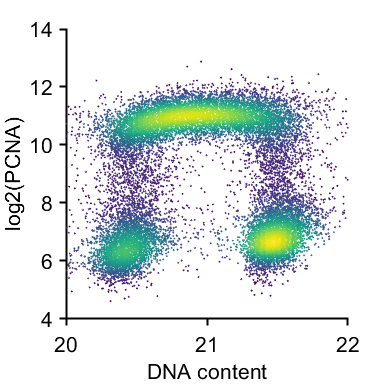

conds=[10];

xval = 'DNA';
yval = 'YFP1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = real(log2(allIF(condition).(xval)));
    ydata =  real(log2(allIF(condition).(yval)));
%     inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
%     xdata = xdata(inds);
%     ydata = ydata(inds);
%     
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([20 22]);
%     ylim([0 10]);
    ylabel('log2(PCNA)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis

end

**Set thresholds**

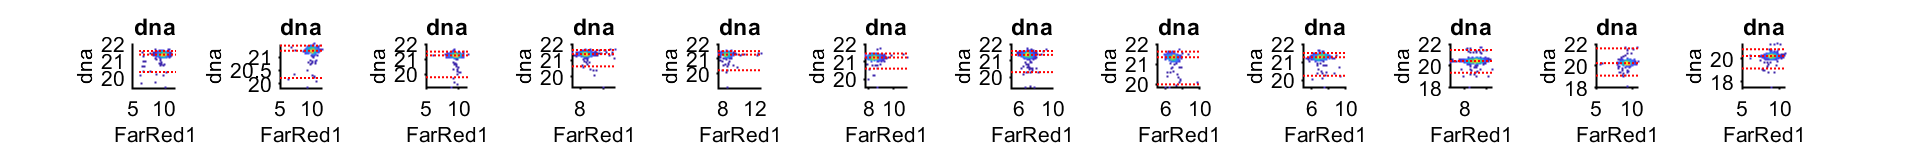

gate = struct();
%% set G1 phase gates
conds=[1:12];

gates = {'dna'};
plotting = {'FarRed1','dna'};
prctiles = {[1 50 99],[1 50 99]};

figure('pos',[0 0 length(conds)*300 length(gates)*300 ])
tiledlayout(length(gates),length(conds))

for j = 1:length(conds)
    for i = 1:length(gates)
        cond = conds(j);
        inds = S(cond).POI_time(:,1) <= 2 &  S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21.75 & isnan(S(cond).POI(:,3));
%         if cond == 10
%             inds = inds & S(cond).FarRed1 < 2^10.25 & S(cond).YFP1 <  2^6.2;
%         end
        ydata = S(cond).(gates{i})(inds,:);
        xdata = S(cond).(plotting{i})(inds,:);
        
        gate(cond).([gates{i} '_G1']) = prctile(ydata, prctiles{i});
        
        nexttile()
        dscatter(log2(xdata),log2(ydata));
        hline( log2(gate(cond).([gates{i} '_G1'])))
        
        ylabel(gates{i});
        xlabel(plotting{i});
        title(gates{i});
        

%         S(cond).g1Vals = ydata;
    end
end

**Check  stain**

numcells = 25700

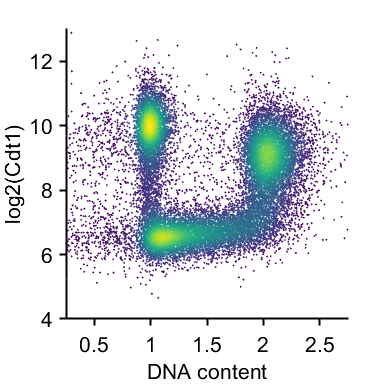

conds=[1];

xval = 'DNA';
yval = 'FarRed1';

xlimits = [.25 2.75];
ylimits = [4 13];

for i = 1:length(conds)
    condition = conds(i);
    xdata = (allIF(condition).(xval)/gate(condition).dna_G1(2));
    ydata =  real(log2(allIF(condition).(yval)));
    inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim(xlimits);
    ylim(ylimits);
    ylabel('log2(Cdt1)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis
    numcells = length(xdata)
 print_pdf([pwd() '\Figs\dnavsCdt1.pdf'])
end

**Check  stain**

numcells = 25292

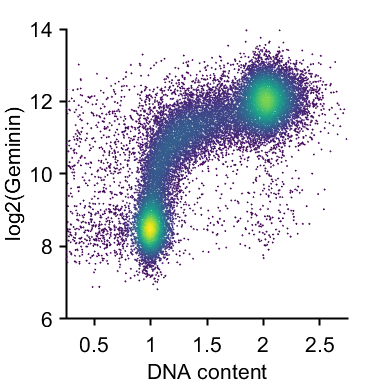

conds=[4];
xval = 'DNA';
yval = 'FarRed1';

xlimits = [.25 2.75];
ylimits = [6 14];

for i = 1:length(conds)
    condition = conds(i);
    xdata = (allIF(condition).(xval)/gate(condition).dna_G1(2));
    ydata =  real(log2(allIF(condition).(yval)));
    inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim(xlimits);
    ylim(ylimits);
    ylabel('log2(Geminin)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis
    numcells = length(xdata)
 print_pdf([pwd() '\Figs\dnavsgem.pdf'])
end

**Check  stain**

numcells = 23294

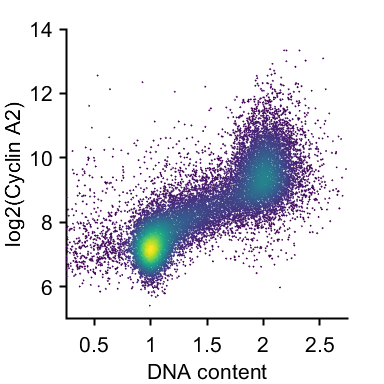

conds=[7];
xval = 'DNA';
yval = 'FarRed1';

xlimits = [.25 2.75];
ylimits = [5 14];

for i = 1:length(conds)
    condition = conds(i);
    xdata = (allIF(condition).(xval)/gate(condition).dna_G1(2));
    ydata =  real(log2(allIF(condition).(yval)));
    inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim(xlimits);
    ylim(ylimits);
    ylabel('log2(Cyclin A2)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis
    numcells = length(xdata)
 print_pdf([pwd() '\Figs\dnavsA2.pdf'])
end

**Check  stain**

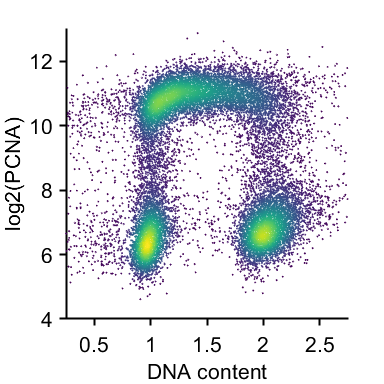

numcells = 21681

conds=[10];
xval = 'DNA';
yval = 'YFP1';

xlimits = [.25 2.75];
ylimits = [4 13];

for i = 1:length(conds)
    condition = conds(i);
    xdata = (allIF(condition).(xval)/gate(condition).dna_G1(2));
    ydata =  real(log2(allIF(condition).(yval)));
    inds = xdata < xlimits(2) & xdata > xlimits(1) & ydata > ylimits(1) & ydata < ylimits(2);% & ~ismember(allIF(condition).fixedSite, [1:6 7 12 13 18 19 24 25 30 31:36 ]);
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim(xlimits);
    ylim(ylimits);
    ylabel('log2(PCNA)');
    xlabel('DNA content');
%     title(conditions{condition,1});
    colormap viridis
    
 print_pdf([pwd() '\Figs\dnavsPCNA.pdf'])
 numcells = length(xdata)
end

**stat test Cdt1 comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

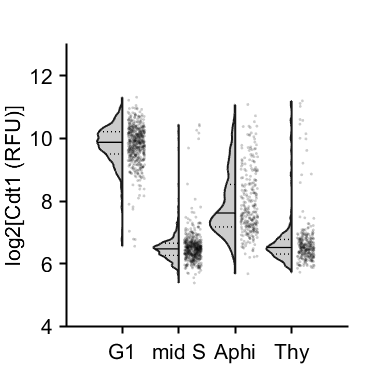

rng(5)
yval = 'FarRed1';

test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 3 &  S(condition).POI_time(:,1) > 1 & S(condition).dna < 2^21.75 & isnan(S(condition).POI(:,3));
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% mid  S phase cell
condition =  1;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,3) <= 3 & S(condition).POI_time(:,3) >= 2 ...
    &  S(condition).dna < 2^22.5;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];

% %%% G2 phase cell
% condition =  1;
% ydata = log2(S(condition).(yval));
% inds = S(condition).POI_time(:,5) <= 3 & S(condition).POI_time(:,5) >= 0 ...
%     &  S(condition).dna > 2^21.5;
% ydata = ydata(inds);
% inds = randsample(length(ydata),1000);
% ydata = ydata(inds);
% % ydata(ydata<0) = [];
% % test{2} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(3,size(ydata))];

%%% Aphi
condition =  2;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];

%%% Thy
condition = 3 ;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(4,size(ydata))];

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','mid S','Aphi','Thy'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 5,'k','filled','MarkerFaceAlpha',.2);
ylabel('log2[Cdt1 (RFU)]')
ylim([4 13])
% xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\Cdt1_compare_scatter.pdf'])

**stat test gem comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

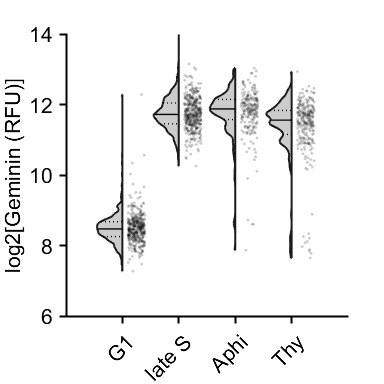

rng(5)
yval = 'FarRed1';

test = {};
ally = [];
group = [];

%%% G1 levels
condition = 4;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 3 &  S(condition).POI_time(:,1) > 1 & S(condition).dna < 2^21.75 & isnan(S(condition).POI(:,3));
ydata = ydata(inds);
inds = randsample(length(ydata),400);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];
% 
% %%% mid  S phase cell
% condition =  4;
% ydata = log2(S(condition).(yval));
% inds = S(condition).POI_time(:,3) <= 3 & S(condition).POI_time(:,3) >= 2 ...
%     &  S(condition).dna < 2^21.5;
% ydata = ydata(inds);
% inds = randsample(length(ydata),1000);
% ydata = ydata(inds);
% % ydata(ydata<0) = [];
% % test{2} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(2,size(ydata))];

%%% late S phase cell
condition =  4;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 18 & S(condition).POI_time(:,1) >= 16 ...
    &  S(condition).dna > 2^22;
ydata = ydata(inds);
inds = randsample(length(ydata),400);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];

%%% Aphi
condition =  5;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),400);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];

%%% Thy
condition = 6;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),400);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(4,size(ydata))];

% %%% G2 levels
% condition = 1;
% inds = S(condition).POI_time(:,5) <= 5 & S(condition).POI_time(:,5) >= 0 ...
%     &  S(condition).dna > 2^21.75;
% ydata = ydata(inds);
% 
% % inds = randsample(length(ydata),700);
% % ydata = ydata(inds);
% 
% test{3} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
% ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
% test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
% cellfun(@median,test)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','late S','Aphi','Thy'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 5,'k','filled','MarkerFaceAlpha',.2);
ylabel('log2[Geminin (RFU)]')
ylim([6 14])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\Geminin_compare_scatter.pdf'])

**stat test A2 comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

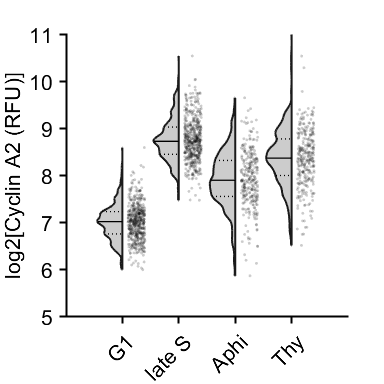

rng(5)
yval = 'FarRed1';

test = {};
ally = [];
group = [];

%%% G1 levels
condition = 7;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 3 &  S(condition).POI_time(:,1) > 1 & S(condition).dna < 2^21.75 & isnan(S(condition).POI(:,3));
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

% %%% mid  S phase cell
% condition =  7;
% ydata = log2(S(condition).(yval));
% inds = S(condition).POI_time(:,3) <= 3 & S(condition).POI_time(:,3) >= 2 ...
%     &  S(condition).dna < 2^21.5;
% ydata = ydata(inds);
% inds = randsample(length(ydata),1000);
% ydata = ydata(inds);
% % ydata(ydata<0) = [];
% % test{2} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(2,size(ydata))];

%%% G2 phase cell
condition =  7;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 18 & S(condition).POI_time(:,1) >= 15 ...
    &  S(condition).dna > 2^22;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];

%%% Aphi
condition =  8;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];

%%% Thy
condition = 9;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
ydata = ydata(inds);
inds = randsample(length(ydata),500);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(4,size(ydata))];

% %%% G2 levels
% condition = 1;
% inds = S(condition).POI_time(:,5) <= 5 & S(condition).POI_time(:,5) >= 0 ...
%     &  S(condition).dna > 2^21.75;
% ydata = ydata(inds);
% 
% % inds = randsample(length(ydata),700);
% % ydata = ydata(inds);
% 
% test{3} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
% ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
% test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
% cellfun(@median,test)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','late S','Aphi','Thy'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 5,'k','filled','MarkerFaceAlpha',.2);
ylabel('log2[Cyclin A2 (RFU)]')
ylim([5 11])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\A2_compare_scatter.pdf'])

**stat test A2 comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

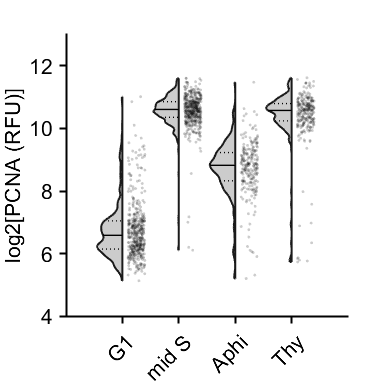

rng(5)
yval = 'YFP1';

test = {};
ally = [];
group = [];

%%% G1 levels
condition = 10;
ydata = log2(S(condition).(yval));
inds =  isnan(S(condition).POI(:,3))  & S(condition).POI_time(:,1) <= 2 &  S(condition).POI_time(:,1) > 1 & S(condition).dna < 2^21 ;
ydata = ydata(inds);
inds = randsample(length(ydata),450);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% mid  S phase cell
condition =  10;
ydata = log2(S(condition).(yval));
inds =    S(condition).POI_time(:,3) <= 3 & S(condition).POI_time(:,3) >= 2 ...
    &  S(condition).dna < 2^21.2;
ydata = ydata(inds);
inds = randsample(length(ydata),450);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];

% %%% G2 phase cell
% condition =  10;
% ydata = log2(S(condition).(yval));
% inds = S(condition).POI_time(:,1) >= 14 ...
%     &  S(condition).dna > 2^21.2 ;
% ydata = ydata(inds);
% inds = randsample(length(ydata),450);
% ydata = ydata(inds);
% % ydata(ydata<0) = [];
% % test{2} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(3,size(ydata))];

%%% Aphi
condition =  11;
ydata = log2(S(condition).(yval));
inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15 ;
ydata = ydata(inds);
inds = randsample(length(ydata),450);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];

%%% Thy
condition = 12;
ydata = log2(S(condition).(yval));
inds =  S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15 ;
ydata = ydata(inds);
inds = randsample(length(ydata),450);
ydata = ydata(inds);
% ydata(ydata<0) = [];
% test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(4,size(ydata))];

% %%% G2 levels
% condition = 1;
% inds = S(condition).POI_time(:,5) <= 5 & S(condition).POI_time(:,5) >= 0 ...
%     &  S(condition).dna > 2^21.75;
% ydata = ydata(inds);
% 
% % inds = randsample(length(ydata),700);
% % ydata = ydata(inds);
% 
% test{3} = ydata;
% ally = [ally; ydata];
% group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
% ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
% test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
% cellfun(@median,test)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','mid S','Aphi','Thy'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 5,'k','filled','MarkerFaceAlpha',.2);
ylabel('log2[PCNA (RFU)]')
ylim([4 13])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\PCNA_compare_scatter.pdf'])

**Compare histograms of Cdt1 no release**

 figure('units','inches','pos',[0 0 4 4]), hold on

condition=1;
    yval = 'DNA';

    ydata = (allIF(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);

   
    
    edges = linspace(.5,2.5,50);
    
    [N,~] = histcounts(ydata,edges,'Normalization','pdf');
    plot(edges(2:end),N,'Linewidth',2);
    num_cells = length(ydata)

num_cells = 78300

    
conds = [2 3 ];
for i=1:length(conds)
    condition=conds(i);
    yval = 'dna';

    ydata = (S(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);
    
    if ismember(condition,[2 3])
        inds = S(condition).POI_time(:,1) <= 17 & S(condition).POI_time(:,1) >= 15;
       ydata = ydata(inds); 
    end
   
    
    edges = linspace(.5,2.5,50);
    
    [N,~] = histcounts(ydata,edges,'Normalization','pdf');
    plot(edges(2:end),N,'Linewidth',2);
    num_cells = length(ydata)
end

num_cells = 943

num_cells = 811

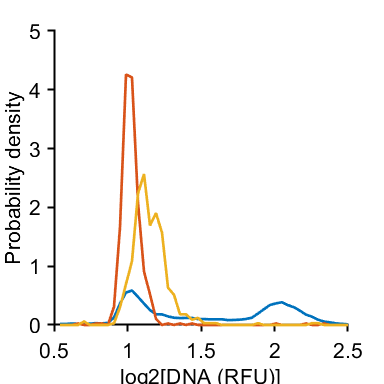

% vline(8.5)
ylabel('Probability density')
xlabel('log2[DNA (RFU)]')
hold off
axis square
print_pdf([pwd() '\Figs\DNA_compare_scatter.pdf'])

**Compare histograms of Cdt1 no release**


conds = [1];
data = {};
for i=1:length(conds)
    condition=conds(i);
    yval = 'DNA';

    ydata = (allIF(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);
    inds = ydata > 0.5 & ydata < 2.5;

   ydata = ydata(inds); 
    data = [data {ydata}];
end

conds = [2 3 ];
for i=1:length(conds)
    condition=conds(i);
    yval = 'dna';

    ydata = (S(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);
    inds = ydata > 0.5 & ydata < 2.5;
    if ismember(condition,[2 3])
        inds = inds & S(condition).POI_time(:,1) <= 18 & S(condition).POI_time(:,1) >= 16;
       
    end
   ydata = ydata(inds); 
    data = [data {ydata}];
end
figure('Units', 'Inches', 'Position', [0, 0, 4, 5])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(3))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','separate','xlabel','DNA content','FontSize',16)

ans = 1×3 cell array
    {'Plot #1: '}    {'Plot #2: '}    {'Plot #3: '}


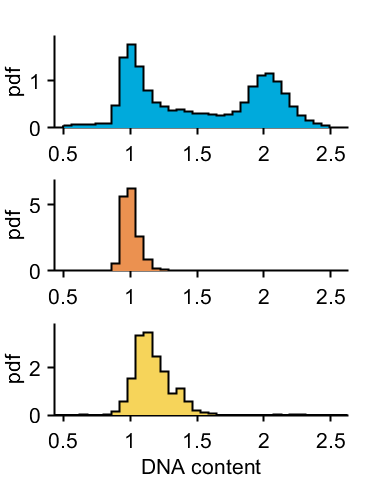

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\DNA_compare_stack.pdf'])

data

data = 1×3 cell array
    {25349×1 double}    {504×1 double}    {478×1 double}


**Compare histograms of Cdt1 no release**


conds = [1];
data = {};
for i=1:length(conds)
    condition=conds(i);
    yval = 'DNA';

    ydata = (allIF(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);
    inds = ydata > 0.5 & ydata < 2.5;

   ydata = ydata(inds); 
    data = [data {ydata}];
end

conds = [2 3 ];
for i=1:length(conds)
    condition=conds(i);
    yval = 'dna';

    ydata = (S(condition).(yval)/gate(condition).dna_G1(2)); %.*S(condition).area);
    inds = ydata > 0.5 & ydata < 2.5;
    if ismember(condition,[2 3])
        inds = inds & S(condition).POI_time(:,1) <= 18 & S(condition).POI_time(:,1) >= 16;
       
    end
   ydata = ydata(inds); 
    data = [data {ydata}];
end
figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(3))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','DNA content','FontSize',16)

ans = 1×3 cell array
    {'Plot #1: '}    {'Plot #2: '}    {'Plot #3: '}


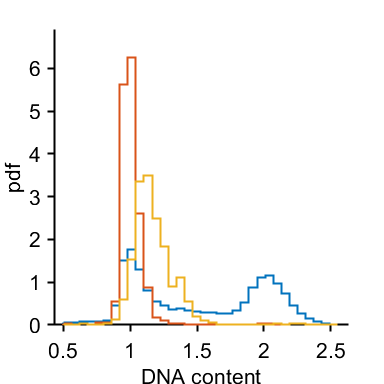

axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\DNA_compare.pdf'])

data

data = 1×3 cell array
    {25349×1 double}    {504×1 double}    {478×1 double}
